# [k-Nearest Neighbors Regression](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression)

k-Nearest Neighbors (k-NN) regression is a type of  non-parametric, instance-based learning algorithm that is used for  regression tasks. It works by predicting the output value of a data  point based on the output values of the k-nearest data points in the  training set. 

The k-NN algorithm has the following steps: 

- Choose the number of neighbors *k* and collect a training set. A set of training samples is (*xs**i**, ys**i*) where *xs**i* is the input (features) vector and *ys**i* is the corresponding target (label) value for each set *i*. 

- Calculate the distance between the data point and all the points in the training set. The distance *d**i* between the test sample *xt* and a stored training sample *xs**i* is usually calculated using the Euclidean distance, where *n* is the number of features in *xs* or *xt*.

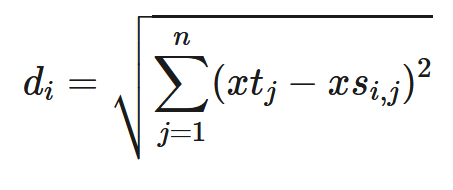

- Select the *k*-nearest points in the training set based on the distance.  

- Predict the output value of the data point as the average of the output values of the *k*-nearest points. k-NN regression finds the prediction for a test sample *xt* by computing the average of the *k* nearest training samples to *xt*. The prediction can be written in the following way, where *ysi* are the target values of the *k*-nearest neighbors to *xt:*

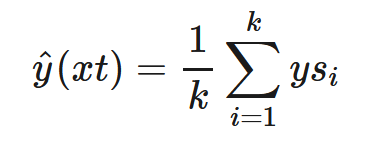

**Advantages:** This algorithm is simple to implement, robust to noisy training data, and effective if training data is large. 

**Disadvantages:** Need to determine the value of *k* and the computation cost is high as it needs to computer the distance of each instance to all the training samples. A feedback loop can be added to determine the number of neighbors. 

**k-Nearest Neighbors Regression in MATLAB**

A custom function such as the one found [here](https://www.mathworks.com/matlabcentral/fileexchange/81893-k-nearest-neighbors-knn-regressor) can be used to do kNN regression in MATLAB. To use this function: download the zipped folder and then unzip it. Make sure the current working directory is the same folder as where this MATLAB file is saved. Then you can call the function within this file.

Below is an example of how to implement k-NN regression in MATLAB using this custom function: 

% Download the zipped folder
url = "https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/65af40e6-bebf-47b5-87f3-c1b55f56a383/5b86fa73-fadd-473c-b625-1df432e08102/packages/zip";
filename = 'kNNReg.zip';
websave(filename,url); 

% Unzip the file
unzip(filename);

% Assume that we have a training set of data points with input features X and output values y
X = [0 1; 1 2; 2 3; 3 4; 4 5];
y = [1 2 3 4 5];

First we'll make a prediction using 3 for k, where k is the number of nearest data points used in making the prediction. 

% Create a k-NN regressor with k=3
NumNeighbors =3;
mdl = kNNeighborsRegressor(NumNeighbors);
mdl = mdl.fit(X,y);

% Predict the output value of a new data point, given k=3
x_new = [1 1];
mdl.predict(x_new)

ans = 2

With k=3 we get a prediction of 2 for the input [1 1] because that's the average output of the three nearest datapoints. If we use k=5 we'll be taking the average of 5 nearest data points instead of just 3. This results in a prediction of 3 instead of 2 because our dataset only has 5 points, and the average of all those outputs is 3.   


% Create a k-NN regressor with k=5
NumNeighbors =5;
mdl = kNNeighborsRegressor(NumNeighbors);
mdl = mdl.fit(X,y);

% Predict the output value of a new data point, given k=5
x_new = [1 1];
mdl.predict(x_new)

ans = 3